# Discretización

## Ventanas

Diseñar 2 ventanas de N=1024 muestras con las funciones dedicadas. Plotearlas en tiempo y en frecuencia.

% Realizamos la discretización de fourier a diferentes ventanas.
N=1024;
w_hamming  = hamming(N);
w_flattop  = flattopwin(N);
w_blackman = blackman(N);
windows    = table(w_blackman,w_flattop,w_hamming);

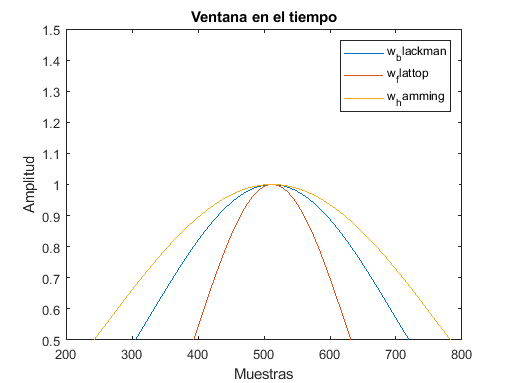


% Ploteamos las muestras
figure
plot(windows{:,:})
legend(windows.Properties.VariableNames)
ylim([0.5 1.5])
xlabel("Muestras")
ylabel("Amplitud")
title("Ventana en el tiempo")

% Ploteamos el espectograma

[Pxx,w_flattop] = periodogram(windows{:,:},[],N,[]);
windows_spectral = array2table(Pxx,"variableNames",windows.Properties.VariableNames)

windows_spectral = 513×3 table
    w_blackman    w_flattop     w_hamming 
    __________    __________    __________

        180.28        47.497         298.1
        128.02        88.725        108.44
        3.3068        39.397     4.616e-05
    4.9259e-09        3.6058    6.4858e-06
      8.68e-08      0.025338    1.8444e-06
    6.1293e-08    1.2538e-09    7.2037e-07
    3.5982e-08    3.9829e-10    3.3869e-07
    2.1411e-08    5.4613e-10    1.8006e-07
     1.328e-08    5.0906e-10    1.0452e-07
    8.5945e-09    4.1074e-10    6.4815e-08
    5.7787e-09    3.1558e-10    4.2321e-08
    4.0165e-09    2.3938e-10    2.8802e-08
    2.8728e-09    1.8193e-10    2.0281e-08
    2.1064e-09     1.394e-10    1.4693e-08
    1.5781e-09    1.0795e-10    1.0905e-08
    1.2048e-09    8.4553e-11    8.2632e-09


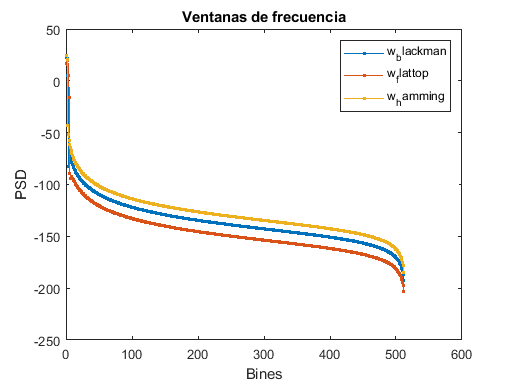


figure
plot(pow2db(windows_spectral{:,:}),".-")
legend(windows.Properties.VariableNames)
xlabel("Bines")
ylabel("PSD")
title("Ventanas de frecuencia")

Generar las siguientes formas de onda con 1024 muestras y guardar cada una en un campo de una tabla.

- 
$$x(t)=cos(4t)$$


- 
$$x(t)=cos(4t)+cos(4.5t)$$


- 
$$x(t)=cos(4t)+cos(8t)
$$


- 
$$x(t)=cos(4t)+0.001cos(8t)$$


Plotear tempralmente y en espacil de frecuencias

x1 = @(t) cos(4*t)                  ;
x2 = @(t) cos(4*t) + cos(4.5*t)     ;
x3 = @(t) cos(4*t) + cos(8*t)       ;
x4 = @(t) cos(4*t) + 0.001*cos(8*t) ;

% valores de evaluación.
t = linspace(0,6,N)'; % Hacemos un vector columna.

% Tabla 
signals = table(x1(t),x2(t),x3(t),x4(t))

signals = 1024×4 table
     Var1       Var2      Var3      Var4  
    _______    ______    ______    _______

          1         2         2      1.001
    0.99972    1.9994    1.9986     1.0007
     0.9989    1.9975    1.9945     0.9999
    0.99752    1.9944    1.9876    0.99851
     0.9956      1.99     1.978    0.99658
    0.99313    1.9844    1.9657     0.9941
    0.99011    1.9776    1.9507    0.99107
    0.98655    1.9695    1.9331    0.98749
    0.98244    1.9602    1.9128    0.98337
    0.97779    1.9497    1.8899     0.9787
    0.97261     1.938    1.8645     0.9735
    0.96689     1.925    1.8366    0.96776
    0.96063    1.9109    1.8063    0.96148
    0.95385    1.8956    1.7735    0.95467
    0.94654    1.8791    1.7384    0.94734
    0.93872    1.8614    1.7011    0.93948


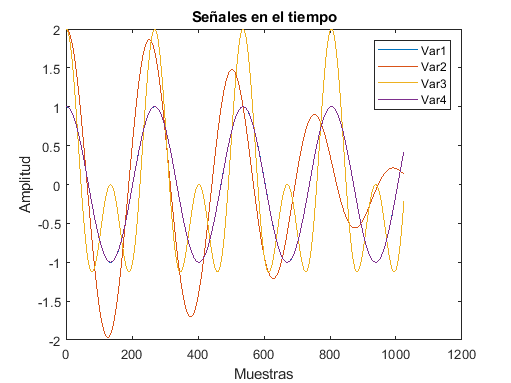


% Ploteamos
figure
plot(signals{:,:})
legend(signals.Properties.VariableNames)
xlabel("Muestras")
ylabel("Amplitud")
title("Señales en el tiempo")

Aplicar las ventanas a cada forma de onda mediante $y(t)=w(t)x(t)$ y alojarlas en distintas tablas

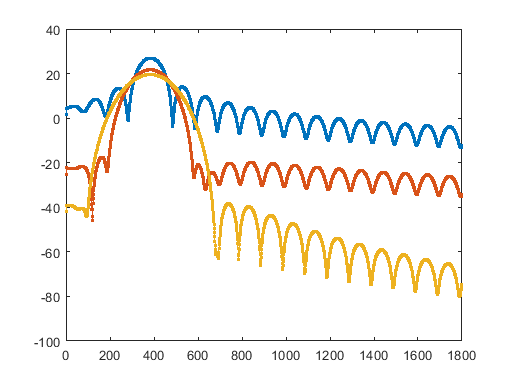

[Pxx,w] = periodogram(signals{:,:},[],100.*N,[]);
signals_rect_spectre = array2table(pow2db(Pxx),"VariableNames",signals.Properties.VariableNames);

[Pxx,w] = periodogram(signals{:,:}.*windows{:,"w_hamming"},[],100.*N,[]);
signals_hamm_spectre = array2table(pow2db(Pxx),"VariableNames",signals.Properties.VariableNames);

[Pxx,w] = periodogram(signals{:,:}.*windows{:,"w_blackman"},[],100.*N,[]);
signals_black_spectre = array2table(pow2db(Pxx),"VariableNames",signals.Properties.VariableNames);


figure
plot([ ...
    signals_rect_spectre{: ,"Var1"} ...
    signals_hamm_spectre{: ,"Var1"} ...
    signals_black_spectre{:,"Var1"} ...
    ],".-")
xlim([0 1800])

Hacer combinaciones de figures en donde se observen:

- Las diferencias de la señal 1 con distintas ventanas

- Las diferencias entre las señales 2-4 con distintas ventanas

Generar las siguientes formas de onda y alojarlas en una tabla

- Sinusoidal

- Triangular

- Diente de sierra

- Cuadrada

Hacer un tiledlayout (subplot) con:

- Su representación en tiempo

- Su representación en frecuencia

Aplicar las ventanas a las formas de onda anteriores y comparar resultados en tiempo y frecuencia.

Variar el número de muestras desde N y desde nfft del periodograma

## Resampling

Hacer upsampling y downsampling de las formas de onda anteriores

f  = 10  ; % Hz
fs = 1e3 ; % Hz
Ts = 1/fs; % s
t = 0:Ts:1 ;

sqr_wave = square(2*pi*f.*t);
sqr_wave_wind = sqr_wave.*windows.w_blackman{:,1000}
figure
plot(t,sqr_wave)


Usar distintos métodos de oversampling (interpolación) para una sección de los datos de cassini

## Detector de picos

Detectar los picos de la forma de onda cuadrada y del audio del buho